clear
clc

load('glass_prop.mat')
load('medium_set.mat')

%declaration of global variables
global beaker_volume beakerinnerdim beakerouterdim beakerheight mantel_A;
global top_A Tinf humidity k_glass rho_glass cp_glass epsilon_glass L_glass;
global heatcontribution_top heatcontribution_mantel kc_coeff h_mantel_coeff;

beaker_volume = glass.beaker_size(2); %m3
beakerinnerdim = glass.inner_diameter(2); %m
beakerouterdim = glass.outer_diameter(2); %m
beakerheight = glass.height(2); %m
[mantel_A, top_A] = coffeCupArea(beakerouterdim,beakerinnerdim);
Tinf = 20.6+273; %room temprature C 
humidity = 0.22; %room humidity
k_glass = glass.heat_conduction;
rho_glass = glass.density;
cp_glass = glass.heat_capacity;
epsilon_glass = glass.emissioncoeff;
L_glass = 1.5e-3;
heatcontribution_top = [];
heatcontribution_mantel = [];


% Initial values for temperature and mass
y0 = [(273.15+80),0.24194];

tint = linspace(0,30.5,62).*60; %[1 2250];

%unoptimized modell

heatcontribution_top = [];
heatcontribution_mantel = [];
kc_coeff = 1;
h_mantel_coeff = 1
[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

R2_model = [0;0;0];
for c1 = linspace(1,5,30) 
    for c2 = linspace(0,1,30)
        h_mantel_coeff = c1;
        kc_coeff = c2;
        
        % ODE solver
        [t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);
        
        SSres_temp = sum((medium(2).beaker(:,2)+273.15-Y(:,1)).^2);
        SStot_temp = sum((medium(2).beaker(:,2)+273.15-mean(medium(2).beaker(:,2)+273.15)).^2);
        R2_temp = 1 - (SSres_temp/SStot_temp);
        
        SSres_mass = sum((medium(2).beaker(:,3)-Y(:,2)*1000).^2);
        SStot_mass = sum((medium(2).beaker(:,3)-mean(medium(2).beaker(:,3))).^2);
        R2_mass = 1 - (SSres_mass/SStot_mass);
        
        R2_model = [R2_model ,[(R2_temp+R2_mass)/2;c1;c2]];
        
    end
end

[R2,i] = max(R2_model(1,:))

R2 = 0.9974

i = 475

best_coeff = [R2_model(2,i),R2_model(3,i)]

best_coeff =     3.0690    0.7931



heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = best_coeff(1);
kc_coeff = best_coeff(2);

[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

% best coeff [3.068965517241379,0.793103448275862]

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = 3.068965517241379;
kc_coeff = 0.793103448275862;

[t,Y]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

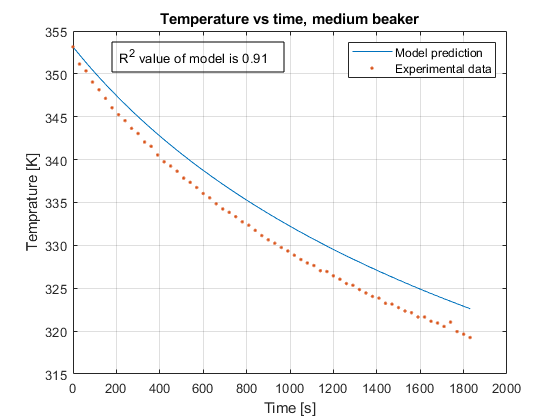

%Plotting experimental data vs modell for temperature
SSres_temp = sum((medium(2).beaker(:,2)+273.15-Y(:,1)).^2);
SStot_temp = sum((medium(2).beaker(:,2)+273.15-mean(medium(2).beaker(:,2)+273.15)).^2);
R2 = 1 - (SSres_temp/SStot_temp);
R2string = sprintf('R^2 value of model is %.2f ',R2);

plot(t,Y(:,1),medium(2).beaker(:,1)*60,medium(2).beaker(:,2)+273.15,'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Temperature vs time, medium beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Temprature [K]')
grid on

%Plotting experimental data vs modell for mass
SSres_mass = sum((medium(2).beaker(:,3)-Y(:,2)*1000).^2);

Reference to a cleared variable Y.

SStot_mass = sum((medium(2).beaker(:,3)-mean(medium(2).beaker(:,3))).^2);
R2 = 1 - (SSres_mass/SStot_mass);

R2string = sprintf('R^2 value of model is %.2f ',R2);


plot(t,Y(:,2)*1000,medium(2).beaker(:,1)*60,medium(2).beaker(:,3),'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Mass vs time, medium beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Mass [g]')
grid on

%plots residual temperature
residual_temp = (medium(2).beaker(:,2)+273.15) - Y(:,1);

plot(t,residual_temp,'+',[t(1) t(end)],[0 0],'--')
%plot([t(1) t(end)],[0 0],'--')


title('Residual for temperature vs time, medium beaker')
legend('Residual temp')
xlabel('Time [s]')
ylabel('Residual [K]')
xlim([t(1) t(end)])
grid on

%plots residual mass
residual_mass = medium(2).beaker(:,3) - Y(:,2)*1000;

plot(t,residual_mass,'*',[t(1) t(end)],[0 0],'--')
%plot([t(1) t(end)],[0 0],'--')


title('Residual for mass vs time, medium beaker')
legend('Residual mass')
xlabel('Time [s]')
ylabel('Residual [K]')
xlim([t(1) t(end)])
grid on

%heat contribution plot
sumheatcontribution = heatcontribution_top(:,1)+heatcontribution_top(:,2)+heatcontribution_top(:,3)+heatcontribution_mantel(:,1)+heatcontribution_mantel(:,2);

heatcontribution_convection = (heatcontribution_top(:,1) + heatcontribution_mantel(:,1))./sumheatcontribution;
heatcontribution_radiation = (heatcontribution_top(:,2) + heatcontribution_mantel(:,2))./sumheatcontribution;
heatcontribution_evaporation = heatcontribution_top(:,3)./sumheatcontribution;

t_heat = linspace(0,37.5,length(sumheatcontribution)).*60;
plot(t_heat,smooth(heatcontribution_convection),t_heat,smooth(heatcontribution_radiation),t_heat,smooth(heatcontribution_evaporation))

title('% heat contribution vs time, medium beaker')
legend('Convection', 'Radiation', 'Evaporation')
xlabel('Time [s]')
ylabel('Heat contribution [%]')
xlim([t_heat(1) t_heat(end)])
grid on

%sensativity analysis kc

h_mantel_coeff = 1;


Y_total = [];
test_parameter = linspace(0,2,50);

for i = test_parameter
kc_coeff = i;
[t,Y_test]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

Y_total = [Y_total,Y_test];

end

residual_temp = [];
for i = linspace(1,length(Y_total(1,:))-1,length(Y_total(1,:))/2)
    residual_temp = [residual_temp, [sqrt(sum((medium(2).beaker(:,2)+273.15-Y_total(:,i)).^2)/length(medium(2).beaker(:,2)))/std(medium(2).beaker(:,2)+273.15)]];
end

residual_mass = [];
for i = linspace(2,length(Y_total(1,:)),length(Y_total(1,:))/2)
    residual_mass = [residual_mass, [sqrt(sum((medium(2).beaker(:,3)-Y_total(:,i)*1000).^2)/length(medium(2).beaker(:,3))/std(medium(2).beaker(:,3)))]];
end

plot(test_parameter,residual_temp,test_parameter,residual_mass)

title('Normalized RMSE using \sigma for experimental data, medium beaker')
subtitle('C_h = 1')
legend('Temperature', 'Mass')
xlabel('C_{kc} coefficient value')
ylabel('Normalized RMSE')
grid on

%sensativity analysis h_mantel

kc_coeff = 1;


Y_total = [];
test_parameter = linspace(0,12,60);

for i = test_parameter
h_mantel_coeff = i;
[t,Y_test]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

Y_total = [Y_total,Y_test];

end

residual_temp = [];
for i = linspace(1,length(Y_total(1,:))-1,length(Y_total(1,:))/2)
    residual_temp = [residual_temp, [sqrt(sum((medium(2).beaker(:,2)+273.15-Y_total(:,i)).^2)/length(medium(2).beaker(:,2)))/std(medium(2).beaker(:,2)+273.15)]];
end

residual_mass = [];
for i = linspace(2,length(Y_total(1,:)),length(Y_total(1,:))/2)
    residual_mass = [residual_mass, [sqrt(sum((medium(2).beaker(:,3)-Y_total(:,i)*1000).^2)/length(medium(2).beaker(:,3))/std(medium(2).beaker(:,3)))]];
end

plot(test_parameter,residual_temp,test_parameter,residual_mass)

title('Normalized RMSE using \sigma for experimental data, medium beaker')
subtitle('C_{kc} = 1')
legend('Temperature', 'Mass')
xlabel('C_h coefficient value')
ylabel('Normalized RMSE')
grid on

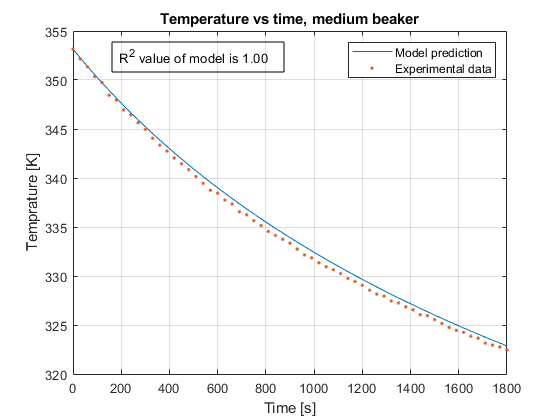

%model verification temperature data set 1

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = 3.068965517241379;
kc_coeff = 0.793103448275862;
y0 = [(273.15+80),0.29831];
tint = linspace(0,medium(1).beaker(end,1),length(medium(1).beaker(:,1))).*60;

[t,Y_validation]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

SSres_temp = sum((medium(1).beaker(:,2)+273.15-Y_validation(:,1)).^2);
SStot_temp = sum((medium(1).beaker(:,2)+273.15-mean(medium(1).beaker(:,2)+273.15)).^2);
R2 = 1 - (SSres_temp/SStot_temp);
R2string = sprintf('R^2 value of model is %.2f ',R2);

plot(t,Y_validation(:,1),medium(1).beaker(:,1)*60,medium(1).beaker(:,2)+273.15,'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Temperature vs time, medium beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Temprature [K]')
grid on

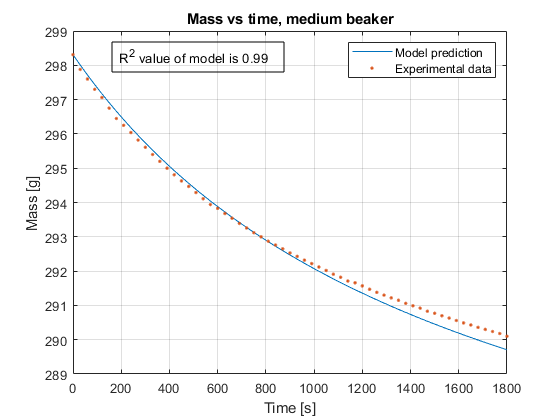

%model verification mass data set 1

heatcontribution_top = [];
heatcontribution_mantel = [];
h_mantel_coeff = 3.068965517241379;
kc_coeff = 0.793103448275862;
y0 = [(273.15+80),0.29831];
tint = linspace(0,medium(1).beaker(end,1),length(medium(1).beaker(:,3))).*60;

[t,Y_validation]  = ode45(@(t,Y)sysdiff(t,Y),tint,y0);

SSres_mass = sum((medium(1).beaker(:,3)-Y_validation(:,2)*1000).^2);
SStot_mass = sum((medium(1).beaker(:,3)-mean(medium(1).beaker(:,3))).^2);
R2 = 1 - (SSres_mass/SStot_mass);

R2string = sprintf('R^2 value of model is %.2f ',R2);


plot(t,Y_validation(:,2)*1000,medium(1).beaker(:,1)*60,medium(1).beaker(:,3),'.')

dim = [.2 .6 .3 .3];
annotation('textbox',dim,'String',R2string,'FitBoxToText','on');

title('Mass vs time, medium beaker')
legend('Model prediction','Experimental data')
xlabel('Time [s]')
ylabel('Mass [g]')
grid on